% 6-DoF linear and non-linear models
syms X_theta_0 X_theta_1s X_delta_e Z_theta_0 Z_theta_1s Z_delta_e M_theta_0 M_theta_1s M_delta_e  % longitudinal stability derivatives
syms Y_Delta_0_0 Y_theta_1c Y_delta_rud L_Delta_theta_0 L_theta_1c L_delta_rud N_Delta_theta_0 N_theta_1c N_delta_rud
syms u v w L M N
syms I_zz I_yy I_xx I_xz X Y Z real
syms p q r 
syms phi theta psi
syms theta_0 theta_1s delta_e   % longitudinal inputs
syms Delta(theta_0) theta_1c delta_r


% Longitudinal state vector
x_lon = [u; w; q; theta]

% Longitudinal inputs
u_lon = [theta_0; theta_1s; delta_e]

% Lateral state vector
x_lat = [v; p; r; phi; psi]

% Lateral inputs
u_lat = [Delta(theta_0); theta_1c; delta_r]

% Rotational matrices
%R-ZYX Euler
Rz = [cos(psi), -sin(psi), 0;
    sin(psi), cos(psi), 0;
    0, 0, 1]
Ry = [cos(theta), 0, sin(theta);
    0, 1, 0;
    -sin(theta), 0, cos(theta)]
Rx = [1, 0, 0;
    0, cos(phi), -sin(phi);
    0, sin(phi), cos(phi)]

% Rotation matrix from body frame to inertial frame
R_Euler = Rz*Ry*Rx


% Longitudinal input matrix
B_lon = [X_theta_0 X_theta_1s X_delta_e;
    Z_theta_0 Z_theta_1s Z_delta_e;
    M_theta_0 M_theta_1s M_delta_e;
    0 0 0]

% Lateral input matrix
B_lat = [Y_Delta_0_0 Y_theta_1c Y_delta_rud;
    L_Delta_theta_0 L_theta_1c L_delta_rud;
    N_Delta_theta_0 N_theta_1c N_delta_rud;
     0 0 0;
     0 0 0]

% Nominal parameters
g = 9.81;  % acceleration of free gravity in m/s^2.
M_a = 3500;  % mass of helicopter in kg



% System parameters

% equations of motion
u_dot = -(w*q - v*r) + (X/M_a) - g*sin(theta);
v_dot = -(u*r - w*p) + (Y/M_a) - g*cos(theta)*sin(phi);
w_dot = -(v*p - u*q) + (Z/M_a) - g*cos(theta)*cos(phi);
% p_dot = ((I_yy - I_zz) * q * r + I_xz*(r_dot + p*q) + L)/I_xx;
q_dot = ((I_zz - I_xx) * r * p + I_xz*(r^2 - p^2) + M)/I_yy;
% r_dot = ((I_xx - I_yy) * p * q + I_xz*(p_dot - q*r) + N)/I_zz;
phi_dot = p + q * sin(phi) * tan(theta) + r * cos(phi) * tan(theta);
theta_dot = q * cos(phi) - r * sin(phi);
psi_dot = q*sin(phi)*sec(theta) + r * cos(phi) * sec(theta);
% 
% x_dot = [u_dot; v_dot; w_dot; p_dot; q_dot; r_dot; phi_dot; theta_dot; psi_dot];
x_lon_dot = [u_dot; w_dot; q_dot; theta_dot]

% u = [theta_0; theta_1s; delta_e; theta_4];
y_lon_sym = [u; w; q; theta];

% Longitudinal state space
A_sym = jacobian(x_lon_dot, x_lon)
B_lon
% B_sym = jacobian(x_lon_dot, u_lon)
% C_sym = jacobian(y_sym, x_lon)
% D_sym = jacobian(y_sym, u)

% linear_ss = ss(A_sym, B_sym, C_sym, D_sym)
% Display equations of motion for inspection
% fprintf("Equations of motion")
% for i = 1:9
%     disp(eval(['eq', num2str(i)]));
% end

% Hover:
% Position & height over and above the surface (respectively) remains constant
% Rotor RPM is constant
% Heading is constant

% Some estimates for the state and control matricies
% Only valid in hover
% Magnitudes may be off

clear
clc
close all

% Final function will look like this with inputs of forward flight speed,
% climb rate etc.
function [A,B,A_lon,B_lon,A_lat,B_lat] = Linearise(x,u)
% Inputs:  x - state vector [u v w p q r phi theta psi]'
%          u - controls vector [theta_0 Delta_theta theta_1c theta_1s delta_r delta_e]'
% Outputs: A - state matrix (9x9)
%          B - Controls matrix (9x6)
%          A_lon - longitudinal states matrix (4x4) [u w q theta]'
%          B_lon - longitudinal controls matrix (4x3) [theta_0 theta_1s delta_e]'
%          A_lat - lateral states matrix (5x5) [v p r phi psi]'
%          B_lat - lateral controls matrix (5x3) [Delta_theta theta_1c delta_r]'


Xu = -0.01;
Xw = 0.01;
Xq = 3.608;
Zu = 0;
Zw = -0.03;
Zq = 0;
Mu = 0.01;
Mw = -0.005;
Mq = -3.75;
A_lon = [Xu Xw Xq -9.81;
         Zu Zw Zq 0    ;
         Mu Mw Mq 0    ;
         0  0  1  0    ];

Xtheta0 = 9.8;
Xtheta1s = -31.1;
Ztheta0 = -295.2;
Ztheta1s = 0;
Mtheta0 = 0;
Mtheta1s = 11;
B_lon = [Xtheta0 Xtheta1s 0;
         Ztheta0 Ztheta1s 0;
         Mtheta0 Mtheta1s 0;
         0       0        0];

Yv = -0.05;
Yp = -0.29;
Yr = 0;
Lv = -0.01;
Lp = -7.5;
Lr = 0.1;
Nv = -0.008;
Np = -1.5;
Nr = -0.25;
A_lat = [Yv Yp Yr 9.81 0;
         Lv Lp Lr 0    0;
         Nv Np Nr 0    0;
         0  1  0  0    0;
         0  0  1  0    0];

Ydeltatheta0 = 13.12;
Ytheta1c = -32.8;
Ldeltatheta0 = 5;
Ltheta1c = 25;
Ndeltatheta0 = -8;
Ntheta1c = -10;
B_lat = [Ydeltatheta0 Ytheta1c 0;
         Ldeltatheta0 Ltheta1c 0;
         Ndeltatheta0 Ntheta1c 0;
         0            0        0;
         0            0        0];

% These will be filled in on the final version
A = zeros(9,9);
B = zeros(9,6);

end

[~,~,A_lon,B_lon,A_lat,B_lat] = Linearise

evalslon = eig(A_lon);
% figure
% plot(real(evalslon),imag(evalslon),'x');

evalslat = eig(A_lat);
% figure
% plot(real(evalslat),imag(evalslat),'x')


% Output Matrix C (3x9 for attitude control: phi, theta, psi)
% Selects which states are outputs
% Rows: phi, theta, psi
% Cols: u, v, w, p, q, r, phi, theta, psi
C = [0 0 0 1];  % observing only theta in the longitudinal system

% Feedforward Matrix D (3x4)
% Represents direct influence of inputs on outputs (usually zero for attitude control)
D = [0 0 0];

heli_ss = ss(A_lon, B_lon, C, D)


heli_ss =
 
  A = 
           x1      x2      x3      x4
   x1   -0.01    0.01   3.608   -9.81
   x2       0   -0.03       0       0
   x3    0.01  -0.005   -3.75       0
   x4       0       0       1       0
 
  B = 
           u1      u2      u3
   x1     9.8   -31.1       0
   x2  -295.2       0       0
   x3       0      11       0
   x4       0       0       0
 
  C = 
       x1  x2  x3  x4
   y1   0   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
 
Continuous-time state-space model.


heli_ss.StateName = {'u-vel'; 'w-vel'; 'pitch rate';
  'pitch angle'};
heli_tf = tf(heli_ss)


heli_tf =
 
  From input 1 to output:
                  1.574 s - 0.01182
  --------------------------------------------------
  s^4 + 3.79 s^3 + 0.1142 s^2 + 0.09814 s + 0.002943
 
  From input 2 to output:
             11 s - 0.201
  -----------------------------------
  s^3 + 3.76 s^2 + 0.00142 s + 0.0981
 
  From input 3 to output:
  0
 
Continuous-time transfer function.



[K, CL, gamma, info] = ncfsyn(heli_tf);
gamma;
p1 = heli_tf(1)


p1 =
 
                  1.574 s - 0.01182
  --------------------------------------------------
  s^4 + 3.79 s^3 + 0.1142 s^2 + 0.09814 s + 0.002943
 
Continuous-time transfer function.
Model Properties


p2 = heli_tf(2)


p2 =
 
             11 s - 0.201
  -----------------------------------
  s^3 + 3.76 s^2 + 0.00142 s + 0.0981
 
Continuous-time transfer function.
Model Properties



% Design objectives for closed-loop control
% High-frequency attentuation of at least 60dB/decade beyond 20 rad/sec.
% Gain margin of at least 6dB.
% Phase margin of at least 45 degrees.

% Use a PI compensator to achieve this
K_PI = pid(1.5, 1.2)


K_PI =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.5, Ki = 1.2
 
Continuous-time PI controller in parallel form.
Model Properties


K_rolloff = tf(1, [1, 200])


K_rolloff =
 
     1
  -------
  s + 200
 
Continuous-time transfer function.
Model Properties


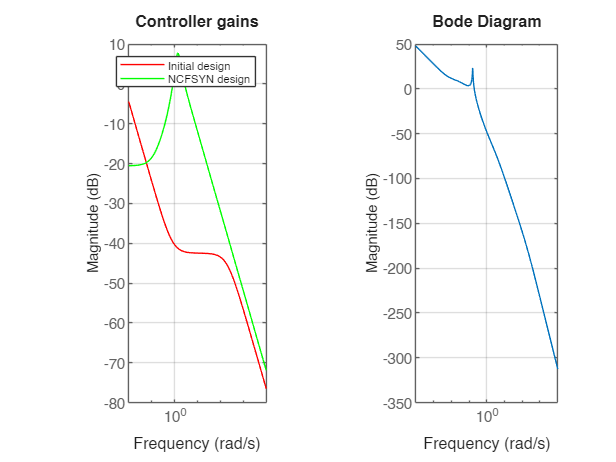

Kprop = K_PI*K_rolloff;
bodemag(p1 * Kprop); grid

% Using ncfsyn to enforce stability
[K_test, ~, gamma] = ncfsyn(p1, 0.7)


K_test =
 
  A = 
             x1        x2        x3        x4
   x1    -5.917    -20.29    -33.98      -106
   x2       0.5         0   -0.5189   0.03118
   x3         0       0.5   -0.6852   0.04116
   x4         0         0    0.5912  -0.02801
 
  B = 
            u1
   x1  -0.0147
   x2   0.1648
   x3   0.2177
   x4  -0.1481
 
  C = 
           x1      x2      x3      x4
   y1  -1.064  -10.03  -16.82  -52.93
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


gamma =    4.824820680395488


K_test = -K_test;
gamma

gamma =    4.824820680395488


allmargin(p1 * K_test)

ans = struct with fields:
     GainMargin: [2.659372388433349 0.023959115651847 1.613030160224221 Inf]
    GMFrequency: [0 0.164593881302951 0.729421924712751 Inf]
    PhaseMargin: [-1.019822081211629e+02 30.604070137166808]
    PMFrequency: [0.023135856622716 0.411205203502449]
    DelayMargin: [1.946441867464575e+02 1.298966510771921]
    DMFrequency: [0.023135856622716 0.411205203502449]
         Stable: 1


### Comparing initial design and NCFSYN

subplot(1, 2, 1)
bodemag(Kprop, 'r', K_test, 'g', {1e-2, 1e4}); grid
legend("Initial design", "NCFSYN design")
title("Controller gains")

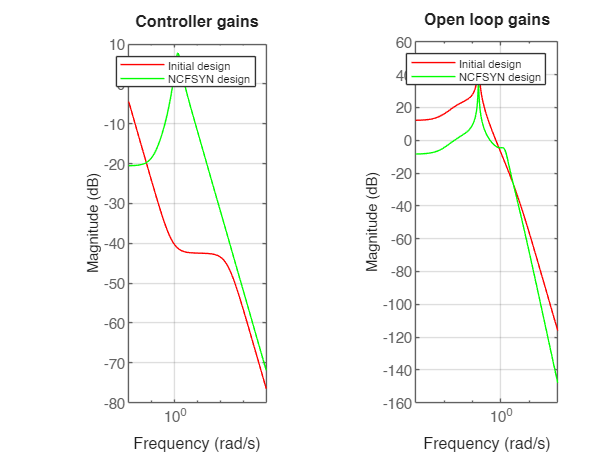


subplot(1, 2, 2)
bodemag(p1, 'r', p1*K_test, 'g', {1e-3, 1e2}); grid
legend("Initial design", "NCFSYN design")
title("Open loop gains")

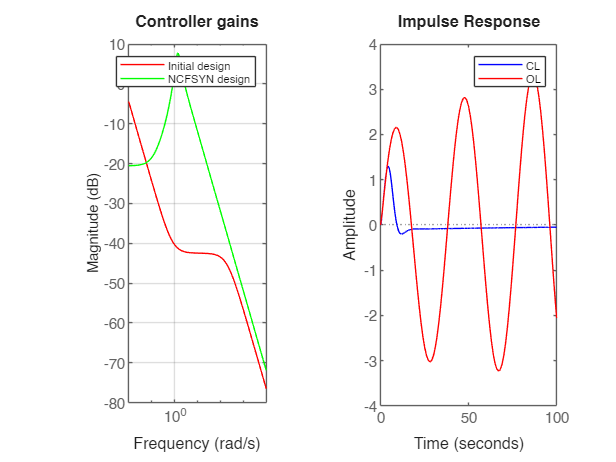

% Open loop response
impulse(feedback(p1, K_test), 'b', p1, 'r', 100);
legend('CL', 'OL')

size(K_test)